# Magnetic Levitation Example

**Pablo Borja**

**pablo.borjarosales@plymouth.ac.uk**

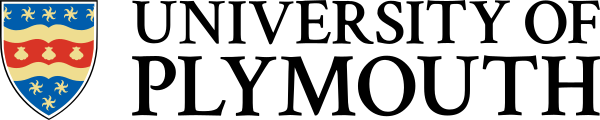

## Analysis

Consider the magnetic levitation system depicted in the following figure

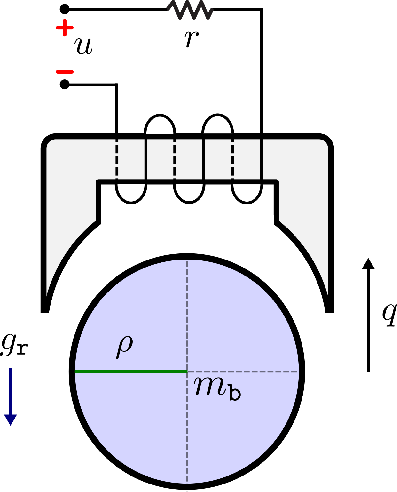

This example illustrates the results of Proposition 4.

### Dynamics

The dynamics of this system are given by


$$\pmatrix{\dot{q} \cr \cr \dot{p} \cr \cr \dot{\varphi}  } = \pmatrix{\frac{{p}}{m_{\tt b}}  \cr -m_{\tt b}g_{\tt r}+\frac{1}{2k}\varphi^{2}  \cr -\frac{r}{k}(\rho - q)\varphi }+\pmatrix{ 0 \cr \cr 0  \cr \cr 1  }u, $$


where $q$ and $p$ represent the position and momentum of the ball, respectively; $\varphi$ denotes the magnetic flux through the coil; $g_{\tt r}$ is the gravitational acceleration; $k$ is a constant parameter associated with coil's number of turns; $m_{\tt b}$ represents the ball's mass; $r$ is the electrical resistance; $\rho$ denotes the ball's radius; $u $ is the voltage provided by the source. This system is subject to the physical constraint $\rho-q>0$.

The set of assignable equilibria is given by

$\mathcal{E} = \left\lbrace  (q,p,\varphi)\in\mathbb{R}^{3} \mid q<\rho; p = 0; \varphi = \displaystyle\sqrt{2km_{\tt b}g_{\tt r}}  \right\rbrace $.

### Control design

Below, we briefly explain how to obtain the closed-loop dynamics. Please see the PDF file "Examples" to understand this part.

For implementation purposes, it's simpler to consider the three dynamics independently because only $\dot{\varphi}$ is affected by the control input. Accordingly,


$$x_{\tt u} =\pmatrix{
             q \cr p
            };  \qquad
 \displaystyle\frac{\partial H(x)}{\partial x_{\tt u}} = \pmatrix{
     m_{\tt b}g_{\tt r} - \frac{1}{2k}\varphi^{2} \cr
     \frac{p}{m_{\tt b}}
    }; \qquad
 x_{\tt a}=\varphi;  \qquad
\displaystyle\frac{\partial H(x)}{\partial x_{\tt a}} = \frac{1}{k}\varphi(\rho - q).$$


This system can be stabilized following using the result of Proposition 4 (see the paper), with


$$\sigma = 1, \quad \Upsilon = \pmatrix{ -1 \cr 0 }, \quad \beta_{\tt u}(x_{\tt u}) = \pmatrix{
     m_{\tt b}g_{\tt r} \cr
     \frac{p}{m_{\tt b}}   }, \quad \beta_{\tt 
a}(x_{\tt a}) = \frac{1}{2k}\varphi^{2}, \quad z(x) = q+\varphi, \quad  \Psi(z) = \frac{1}{2}K_{\tt z}\left( q+\varphi-q_{\star}-\sqrt{2km_{\tt b}g_{\tt r}}\right)^2-m_{\tt b}g_{\tt r}(q+\varphi).$$


Therefore,


$$\frac{\partial H_{\tt d}(x)}{\partial x} = \pmatrix{ K_{\tt z}(q+\varphi-q_{\tt d}-\varphi_{\tt d})-m_{\tt b}g_{\tt r} \cr 0 \cr K_{\tt z}(q+\varphi-q_{\tt d}-\varphi_{\tt d})-m_{\tt b}g_{\tt r}} + \pmatrix{
     m_{\tt b}g_{\tt r} \cr
     \frac{p}{m_{\tt b}} \cr  \frac{1}{2k}\varphi^{2} }$$


and the control law reduces to


$$\begin{array}{rcl}
u &=& -\sigma\Upsilon^{\top}F_{\tt uu}^{\top}(x)\frac{\partial H_{\tt d}(x)}{\partial x_{\tt u}}+F_{\tt aa}(x)\left(\frac{\partial H_{\tt d}(x)}{\partial x_{\tt
a}}-\frac{\partial H(x)}{\partial x_{\tt a}}  \right)-K_{\tt di}\frac{\partial H_{\tt d}(x)}{\partial x_{\tt a}}- F_{\tt au}(x)\frac{\partial H(x)}{\partial x_{\tt u}}\\
&=& -\frac{p}{m_{\tt b}}-(r+K_{\tt di})\left(K_{\tt z}(q+\varphi-q_{\tt d}-\varphi_{\tt d})-m_{\tt b}g_{\tt r}+ \frac{1}{2k}\varphi^{2}\right)+\frac{r}{k}\varphi(\rho - q).
\end{array}$$


Finally, to obtain the closed-loop dynamics, we substitute the control law $u$ obtained above into


$$\dot{\varphi} = -\frac{r}{k}\varphi(\rho - q)+u.$$


## Simulation

### Parameters for Simulation

We define the plant's parameters

mb = 0.1; 
rho = 0.05; 
k = 0.01; 
gr = 9.8; 
r = 8; 
qd2 = -0.45;
phid2 = sqrt(2*mb*gr*k);

parameters = [mb, rho, k, gr, r, qd2, phid2]';

We set the initial conditions and final time

IC = [-0.55 0 0];% Modify to simulate different initial conditions
T = 13; % Modify if you want to simulate a longer or shorter period

### Obtaining the Trajectories

[t,x] = ode23(@(t,x)maglev(x,parameters),[0,T],IC); 

### Plotting the Trajectories

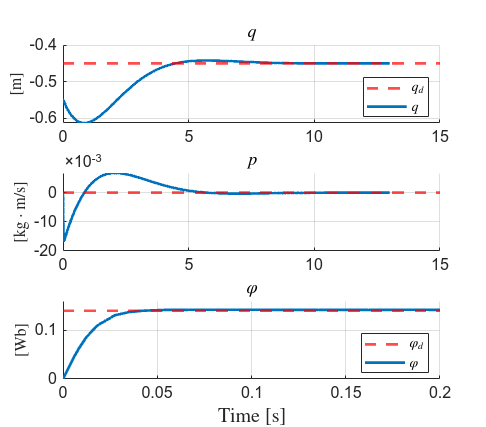

close all

% Position

subplot(3, 1, 1)
yline(qd2, 'r--', 'LineWidth', 2);
grid on
hold on 
plot(t,x(:,1),'LineWidth',2)
hold off
title('$q$','interpreter','latex','FontSize',15)
set(gca,'FontSize',12)
legend('$q_{d}$','$q$','interpreter','latex','Location','SouthEast')
ylabel('[m]','interpreter','latex','FontSize',12)

% Momentum

subplot(3, 1, 2)
yline(0, 'r--', 'LineWidth', 2);
grid on
hold on 
plot(t,x(:,2),'LineWidth',2)
hold off
title('$p$','interpreter','latex','FontSize',15)
set(gca,'FontSize',12)
ylabel('[kg$\cdot$m/s]','interpreter','latex','FontSize',12)

% Flux

subplot(3, 1, 3)
yline(phid2, 'r--', 'LineWidth', 2);
grid on
hold on 
plot(t,x(:,3),'LineWidth',2)
hold off
title('$\varphi$','interpreter','latex','FontSize',15)
set(gca,'FontSize',12)
set(gcf,'position',[10 10 740 650])
legend('$\varphi_{d}$','$\varphi$','interpreter','latex','Location','SouthEast')
xlabel('Time [s]','interpreter','latex','FontSize',15)
ylabel('[Wb]','interpreter','latex','FontSize',12)
axis([0 .2 0 .16])

## Function

You don't need to run this section.

function dx = maglev(x,parameters)

mb = parameters(1);
rho = parameters(2);
k = parameters(3);
gr = parameters(4);
r = parameters(5);
qd = parameters(6);
phid = parameters(7);

% States

q = x(1);
p = x(2);
phi = x(3);

% Controller

u = -p/mb+r*(phi*(rho-q)/k)-r*(0.08*(q+phi-qd-phid)-mb*gr+phi^2/(2*k)); %We are not injecting damping because the system has natural damping 

dx = [p/mb;-mb*gr+phi^2/(2*k);-r*(phi*(rho-q)/k)+u];
 
end